# Gradiente

Imagina la función f(x,y), esta vive en : $R^2 \to R$, es decir teniendo 2 variables independientes la salida es de una variable dependiente lo que nos lleva a la grafica de una superficie. El gradiente de f(x,y) $"\nabla \mathrm{f"}$ es un campo vectorial (una función vectorial pero mas chevere) que vive en el reino de $R^2 \to R^2 \ldotp$ El gradiente de f no es el vector normal al plano tangente pero se usa para construirlo ("Aclaro esto porque muchos suelen confundirse"). Este esta construido de la siguiente forma: $\nabla f=\left\langle \frac{\partial }{\partial x}f,\frac{\partial }{\partial y}f\right\rangle$ "un vector construido a partir de las derivadas parciales"

## Función o Superficie:

Nuestra función f(x,y) es una superficie. Es util entender la diferencia  entre plano, region, superficie y como construir un plano a partir de un vector y un punto cualquiera en la superficie. 

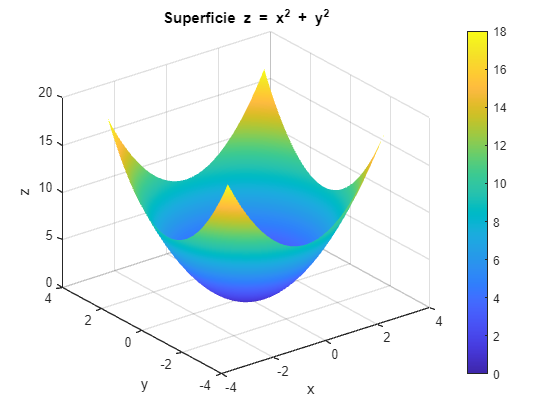

% Dominio
[x,y] = meshgrid(-3:0.1:3, -3:0.1:3);

% Funcion
z = x.^2 + y.^2;

% Grafica de la superficie
figure
surf(x,y,z)
xlabel('x')
ylabel('y')
zlabel('z')
title('Superficie z = x^2 + y^2')
shading interp
colorbar

## Gradiente de la Función o Superficie: 

La gradiente de nuestra función f vive en el espacio bidimensional. Hablando especificamente el gradiente no es una función vectorial solamente, es un campo vectorial, su grafica no es una curva donde la entrada es un punto (x,y) y la salida es una coordenada. Su grafica es una en donde la entrada es un punto del plano (x,y) y la salida es un vector asociado a ese punto. La gradiente de f es util porque nos da información sobre puntos criticos, minimos locales y globales, f habla de optimizacion. Si te das cuenta el cambio en el punto (0,0) es cero esto se debe a que en la grafica de la funcion original encontramos un minimo en este caso global.

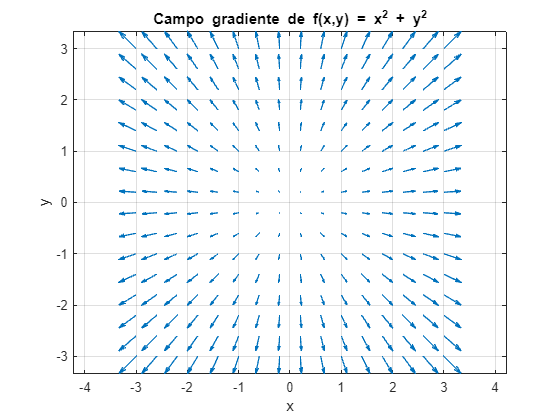

% Dominio (el mismo)
[x,y] = meshgrid(-3:0.4:3, -3:0.4:3);

% Componentes del gradiente
fx = 2*x;
fy = 2*y;

% Campo vectorial del gradiente
figure
quiver(x,y,fx,fy)
xlabel('x')
ylabel('y')
title('Campo gradiente de f(x,y) = x^2 + y^2')
axis equal
grid on

## Función implicita

Las funciones implicitas no se visualizan (en este ejemplo especifico), no puedes visualizar una función $G\left(x,y,z\right)$ porque se encuentra en 4D. Estas se usan para describir restricciones geométricas. Sin embargo si podemos visualizar la gradiente de la funcion implicita.

## Gradiente de la Función Implicita

Para obtener la gradiente de la función implicita de f simplemente tienes que volver implicita la función y encontrar sus derivadas parciales en cada componente, como la componente de z es -z su derivada parcial viene a ser -1. La gradiente de la funcion implicita de f vive en el plano $R^3$. Como se menciono antes, la información que podemos sacar de esta gradiente no es sobre optimización sino de sentido geometrico, podemos saber como esta inclinada la superficie en cada punto. Esta gradiente si muestra el vector perpendicular a el plano tangente en cada punto evaluado. 


$$\begin{array}{l}
F\left(x,y,z\right)=f\left(x,y\right)-z\\
n=\left(\mathrm{fx}\left(\mathrm{xo},\mathrm{yo}\right),\mathrm{fy}\left(\mathrm{xo},\mathrm{yo}\right),-1\right)
\end{array}$$


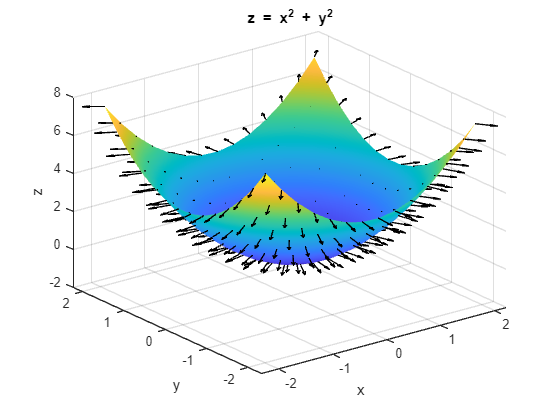

% Dominio
[x,y] = meshgrid(-2:0.3:2, -2:0.3:2);

% Superficie
z = x.^2 + y.^2;

figure
surf(x,y,z)
shading interp
xlabel('x')
ylabel('y')
zlabel('z')
title('z = x^2 + y^2')
hold on

% Gradiente de la funcion implicita F = x^2 + y^2 - z
Fx = 2*x;
Fy = 2*y;
Fz = -ones(size(z));   % <- CLAVE: size(z), no size(x)

% Normalizar (solo para visualizacion)
N = sqrt(Fx.^2 + Fy.^2 + Fz.^2);
Fx = Fx ./ N;
Fy = Fy ./ N;
Fz = Fz ./ N;

% Dibujar normales
quiver3(x,y,z,Fx,Fy,Fz,0.5,'k')